# ODE Numeric

We solve the equation for harmonic oscillator:

$% MathType!MTEF!2!1!+-
% feaagKart1ev2aaatCvAUfeBSjuyZL2yd9gzLbvyNv2CaerbuLwBLn
% hiov2DGi1BTfMBaeXatLxBI9gBamXvP5wqSX2qVrwzqf2zLnharyqw
% 1bYrVrhAPngivLeitvwBPXwANHgDaebbnrfifHhDYfgasaacH8srps
% 0lbbf9q8WrFfeuY-Hhbbf9v8qqaqFr0xc9pk0xbba9q8WqFfea0-yr
% 0RYxir-Jbba9q8aq0-yq-He9q8qqQ8frFve9Fve9Ff0dmeaabaqaci
% GacaGaaeqabaWaceaaeaaakeaaceWG4bGbamaacqGHRaWkcaaIYaGa
% aGynaiaadIhacqGH9aqpcaaIWaaaaa!458C!
\[\ddot x + 25x = 0\]$tspan

First we specify x1(t) and x2(t):


$$% MathType!MTEF!2!1!+-
% feaagKart1ev2aaatCvAUfeBSjuyZL2yd9gzLbvyNv2CaerbuLwBLn
% hiov2DGi1BTfMBaeXatLxBI9gBamXvP5wqSX2qVrwzqf2zLnharyqw
% 1bYrVrhAPngivLeitvwBPXwANHgDaebbnrfifHhDYfgasaacH8srps
% 0lbbf9q8WrFfeuY-Hhbbf9v8qqaqFr0xc9pk0xbba9q8WqFfea0-yr
% 0RYxir-Jbba9q8aq0-yq-He9q8qqQ8frFve9Fve9Ff0dmeaabaqaci
% GacaGaaeqabaWaceaaeaaakeaadaGabaabaeqabaGabmiEayaacaWa
% aSbaaSqaaiaaigdaaeqaaOWaaeWaaeaacaWG0baacaGLOaGaayzkaa
% Gaeyypa0JaamiEamaaBaaaleaacaaIYaaabeaakmaabmaabaGaamiD
% aaGaayjkaiaawMcaaaqaaiqadIhagaGaamaaBaaaleaacaaIYaaabe
% aakmaabmaabaGaamiDaaGaayjkaiaawMcaaiabg2da9iabgkHiTiaa
% ikdacaaI1aGaeyyXICTaamiEamaaBaaaleaacaaIXaaabeaakmaabm
% aabaGaamiDaaGaayjkaiaawMcaaaaacaGL7baaaaa!591E!
\[\left\{ \begin{array}{l}
{{\dot x}_1}\left( t \right) = {x_2}\left( t \right)\\
{{\dot x}_2}\left( t \right) =  - 25 \cdot {x_1}\left( t \right)
\end{array} \right.\]$$


Now we can code the function:

% function xdot = harmOs(t,x)
%     xdot = [x(2);-25*x(1)];
% end

Also replace t with ~

% function xdot = harmOs(~,x)
%     xdot = [x(2);-25*x(1)];
% end

and save it in .m file without the simbols for comment %.

# In this part we call the function:

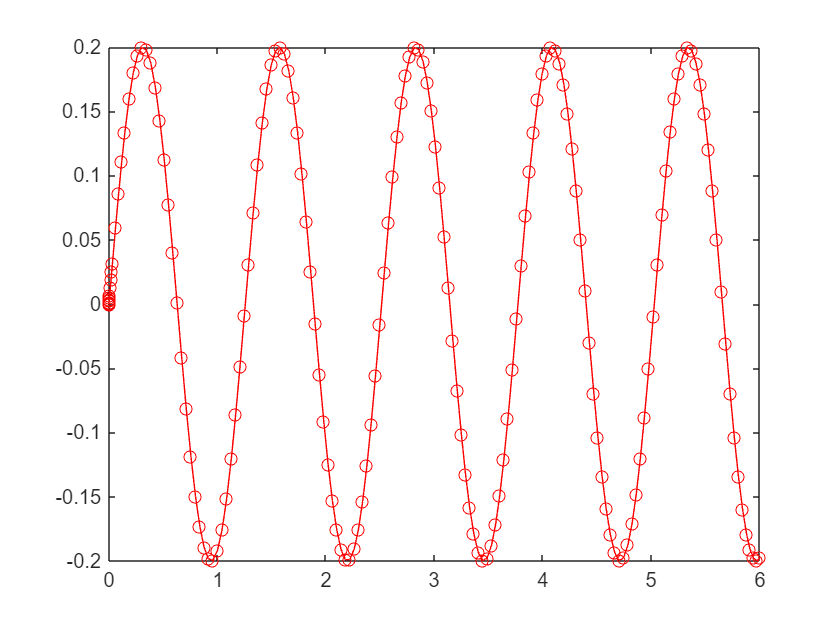

tspan = [0 6];
x0 = [0; 1];
[t,x] = ode45(@harmOs,tspan, x0);
plot(t,x(:,1),'-or'); % Plot a red curve with o.

You can add legend and labels for axes.

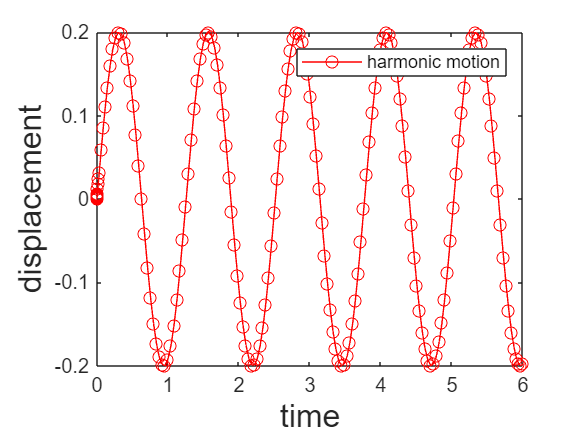

legend('harmonic motion');
xlabel('time','Fontsize',16);
ylabel('displacement','Fontsize',16);

Or we can plot velosity x2(t)

plot(t,x(:,2),'-+g'); % Plot a green curve with +.


You can plot both using 'hold on' and 'hold off' comands. 

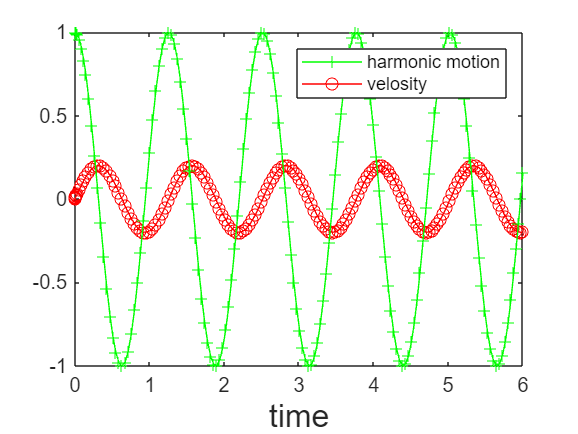

hold on
plot(t,x(:,1),'-or');
plot(t,x(:,2),'-+g');
legend('harmonic motion', 'velosity');
xlabel('time','Fontsize',16);
hold off

Or you can try subplot!